# Reserve Variance Live Script 2

## Change Folder

cd("F:\OneDrive - Queensland University of Technology\Research Assistant " ...
    + "Work (OD)\Reserve Variance (OD)\Code")

cd("C:\Users\sowen\OneDrive - Queensland University of Technology\" + ...
    "Research Assistant Work (OD)\Reserve Variance (OD)\Code")

## Load Data

if ~exist("workspaceVarReserveVariance", 'var')
    load matlabReserveVariance.mat
    setInterpLatex()
end

## Save Data

 if exist("workspaceVarReserveVariance", 'var')
     clearVarsArray = clearVars();
     clear(clearVarsArray{:})
     clear clearVarsArray
     save matlabReserveVariance.mat
 end

% set the default intepreter to latex
setInterpLatex()

## Contents

Checking the Larval Contribution vs Biomass by Connectivity

Investigating Differences Between Regions

Investigating Population CVs of Individual Reefs

Setting Up Cape Study Area

Setting Up Cairns Study Area

Running New Simulations

## Assumptions / Notes

## Checking Larval Contribution vs Biomass by Connectivity

% basically, wanna see if you would get similar outcomes if you didn't have
% age class structured data

% basically, I'm just gonna run my metapopulation model a few times and
% compare the two
popMatTest = baseMetapopModel(areaStructGBR.conMats, ...
        areaStructGBR.areas, areaStructGBR.initPop, simStruct.tWarmup, ...
        specStructCT, randStruct);

% ok, now need to calcaluate the metrics for each of the reefs and each of
% the times
size(popMatTest)

ans =         1903          14          20


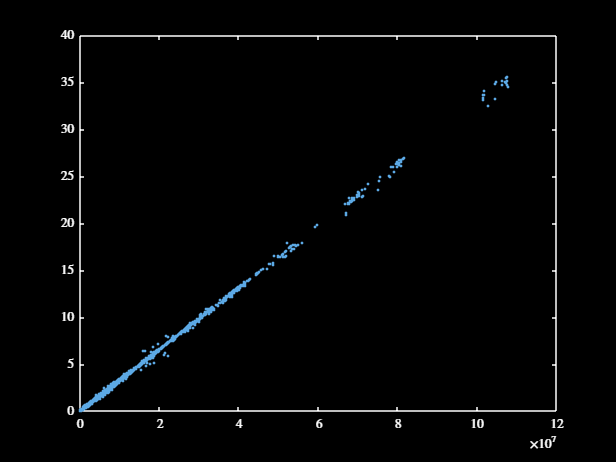


% order the connectivity matrices used so that it works with my above
% method
conMatsCell = cell(1, size(popMatTest, 3));
for t = 1:simStruct.tWarmup
    conMatsCell{t} = areaStructGBR.conMats{randStruct.sequence(t)};
end

% calculate the larval contribution and biomass
larvContVals = calcLarvalContrib(popMatTest, specStructCT.fecundVec, ...
    conMatsCell);
larvContVals = larvContVals(:);
biomassConnVals = calcBiomass(popMatTest, specStructCT.weightings);

% multiply biomass values by connectivity
for r = 1:size(popMatTest, 1)
    for t = 1:size(popMatTest, 3)
        biomassConnVals(r, t) = biomassConnVals(r, t) ...
            * sum(conMatsCell{t}(r, :));
    end
end
biomassConnVals = biomassConnVals(:);

% plot that shit
figure
plot(larvContVals, biomassConnVals, '.')
darkFig()


% looks pretty solid
corr(biomassConnVals, larvContVals)

ans = 0.9999


% ok so perfect, that's far too high of a value to ignore, lfg

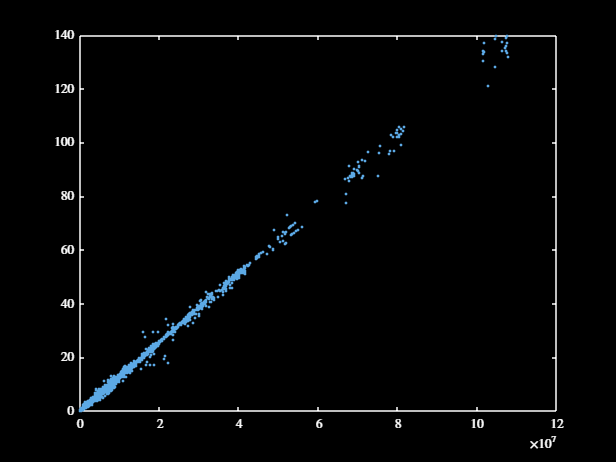

% let's try the same on just population counts
popVals = squeeze(sum(popMatTest, 2));

% multiply population values by connectivity
for r = 1:size(popMatTest, 1)
    for t = 1:size(popMatTest, 3)
        popVals(r, t) = popVals(r, t) * sum(conMatsCell{t}(r, :));
    end
end
popVals = popVals(:);

% plot that shit
figure
plot(larvContVals, popVals, '.')
darkFig()

corr(popVals, larvContVals)

ans = 0.9994


% again lfg, very solid

## Investigating Differences Between Regions

% gonna first grab that plot of the correlations across each area back -
% fuck i need to calculate them again because I was avoiding storing them
corrMatSwains = calcLarvalCorr(areaStructSwains.conMats); 

% calculate the autocorrelations for the coral data
corrMatTowns = calcLarvalCorr(areaStructTowns.conMats);

% calculate the autocorrelations for the SLIM data
corrMatNorth = calcLarvalCorr(areaStructNorth.conMats);

% calculate the correlations across the entire reef system
corrMatCT = calcLarvalCorr(conMatsCT);

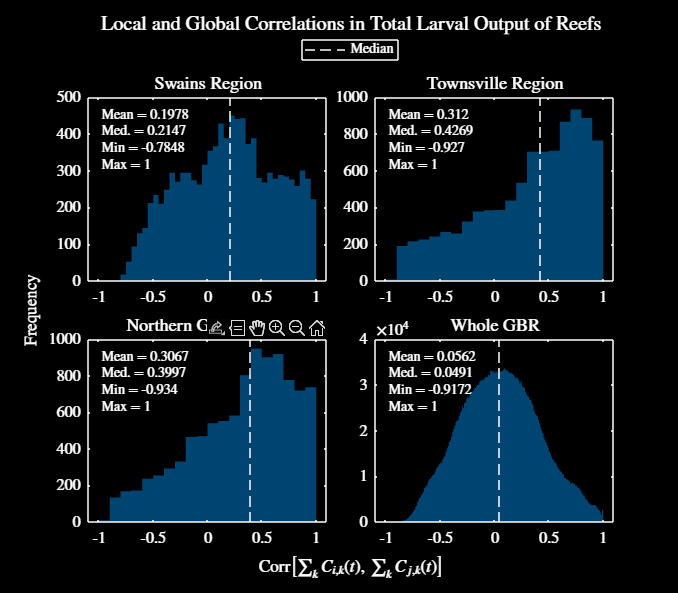

% now plot the stuff
figure
plotConnectivityStats({corrMatSwains(:), corrMatTowns(:), corrMatNorth(:), ...
    corrMatCT(:)}, "correlationLoc", ["Swains Region", "Townsville Region", ...
    "Northern GBR Region", "Whole GBR"])
setFontSize(13)
figResize(1.4, 1.2)
darkFig()

% this fuckery was to try and get matlab to do a lightmode figure by
% default but it didn't work

% get(0,'Factory')
% set(0,'defaultfigurecolor',[1 1 1])
% set(0,'defaultFigureColor',[1 1 1])
% set(0, 'defaultFigureInvertHardcopy', 'on')
% set(groot, 'DefaultAxesXLabelColor', {'k'})
% set(groot,'defaultFigureColor','w')
% set(groot,'defaultAxesColor','w')
% set(groot,'defaultTextColor','k')
% set(groot,{'DefaultAxesXColor','DefaultAxesYColor', ...
%     'DefaultAxesZColor'},{'k','k','k'})
% set(groot, 'DefaultLegendColor', 'w')
% set(groot, 'DefaultLegendTextColor', 'k')
% set(groot, 'DefaultLegendEdgeColor', 'k')

% eventually, should fix up all my groot stuff

% next, look at the CV values for each area
[meanConnCT, stdConnCT, ~, ~] = connectivityAnalysisReef( ...
    areaStructGBR.conMats, eps);

[meanConnCTSwains, stdConnCTSwains, ~, ~] ...
    = connectivityAnalysisReef(areaStructSwains.conMats, eps);

[meanConnCTTowns, stdConnCTTowns, ~, ~] ...
    = connectivityAnalysisReef(areaStructTowns.conMats, eps);

[meanConnCTNorth, stdConnCTNorth, ~, ~] ...
    = connectivityAnalysisReef(areaStructNorth.conMats, eps);

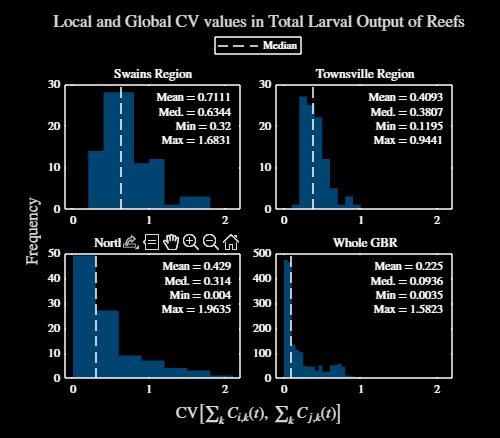

figure
plotConnectivityStats({stdConnCTSwains ./ meanConnCTSwains, ...
    stdConnCTTowns ./ meanConnCTTowns, stdConnCTNorth ./ meanConnCTNorth, ...
    stdConnCT ./ meanConnCT}, "CVLoc", ["Swains Region", ...
    "Townsville Region", "Northern GBR Region", "Whole GBR"])
figResize(1.4, 1.2)
darkFig()


% hmmmm - this is not very good really

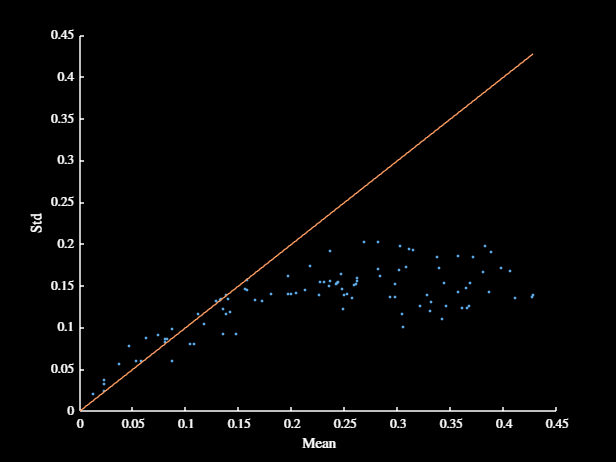

figure
hold on
plot(meanConnCTSwains, stdConnCTSwains, '.')
plot([0, max(meanConnCTSwains)], [0, max(meanConnCTSwains)])
xlabel('Mean')
ylabel('Std')
darkFig()

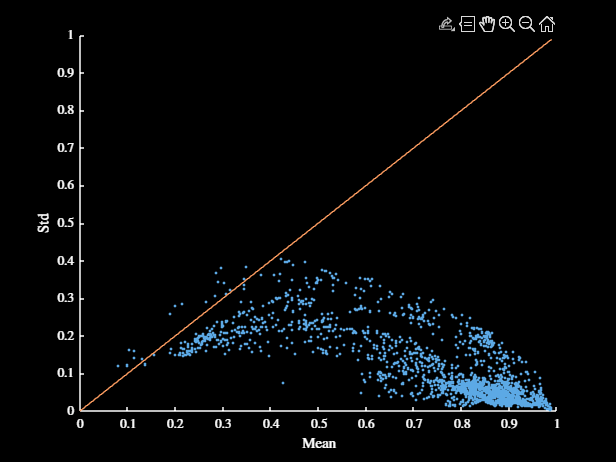

figure
hold on
plot(meanConnCT, stdConnCT, '.')
plot([0, max(meanConnCT)], [0, max(meanConnCT)])
xlabel('Mean')
ylabel('Std')
darkFig()

% clear some stuff
clear meanConnCTSwains meanConnCTTowns meanConnCTNorth meanConnCT ...
    stdConnCTSwains stdConnCTTowns stdConnCTNorth stdConnCT

% idea - could look into the CVs at individual reefs in terms of evaluating
% the solution methodologies, rather than looking at biomass as a whole -
% probably worthwhile to do, and could be a saving grace really

% how would I compare? perhaps with the population CVs at each reef? hmmm,
% if I don't do that it will be hard to reconcile differences between base
% population sizes

% idea - could just plot the average variance or something like that,
% although this doesn't necessarily tell the full story - here, I think
% perhaps plotting the average CV could be a better metric perhaps - I
% think I should look into this honestly, could be kinda big

## Investigating Population CVs of Individual Reefs

% so this is going to be a big fuckaround, but I'm gonna wanna re-run my
% models with the MPAs already chosen etc etc, but this time measure the
% CVs of individual reef populations, in the hope we see that they're
% better under our larval contribution method

% ok, let's have a quick recap on how these methods function
simStructFin

simStructFin = struct with fields:
       tWarmup: 20
          tObs: 20
          tMPA: 40
    warmupSeqs: {100×1 cell}
       obsSeqs: {100×1 cell}
       mpaSeqs: {100×1 cell}
     resources: 0.3300


simStructFin.warmupSeqs

ans = 100×1 cell array
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}
    {20×1 double}


simOutCellTowns

simOutCellTowns = 1×14 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


simOutCellTowns{1}

ans = struct with fields:
             mpaSel: {100×1 cell}
         objFuncTot: [100×1 double]
          objFuncTS: {100×1 cell}
      objFuncExpVal: [100×1 double]
         objFuncVar: [100×1 double]
    objFuncTotRetro: [100×1 double]
     objFuncTSRetro: {100×1 cell}
           exitFlag: [100×1 double]
       methodStruct: [1×1 struct]


simOutCellTowns{1}.mpaSel

ans = 100×1 cell array
    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]}
    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]}
    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]}
    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]}
    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0

simOutCellTowns{1}.mpaSel{1}

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% alright, gonna need to write a function that can now go and redo all of
% these xd

var1 = 100

% let's see how quick this mf is
datestr(now, 'HH:MM')

ans = '09:43'

rerunMPASimulation(simStructFin, areaStructSwains, areaStructGBR, ...
    specStructCT, randStructFin, actionStructFin, simOutCellSwains{5})

% before I re-run this, gonna quickly save a copy of the simOutStructs so
% that I don't accidentally somehow screw it up
save simOutStructs.mat simOutCellTowns simOutCellSwains simOutCellNorth

% alright, let's re-run this shit for the Swains first
for m = 1:length(simOutCellSwains)
    simOutCellSwains{m} = rerunMPASimulation(simStructFin, ...
        areaStructSwains, areaStructGBR, specStructCT, randStructFin, ...
        actionStructFin, simOutCellSwains{m});
end

% now for the Townsville region
for m = 1:length(simOutCellTowns)
    simOutCellTowns{m} = rerunMPASimulation(simStructFin, ...
        areaStructTowns, areaStructGBR, specStructCT, randStructFin, ...
        actionStructFin, simOutCellTowns{m});
end

% now for the north of the GBR
for m = 1:length(simOutCellNorth)
    simOutCellNorth{m} = rerunMPASimulation(simStructFin, ...
        areaStructNorth, areaStructGBR, specStructCT, randStructFin, ...
        actionStructFin, simOutCellNorth{m});
end

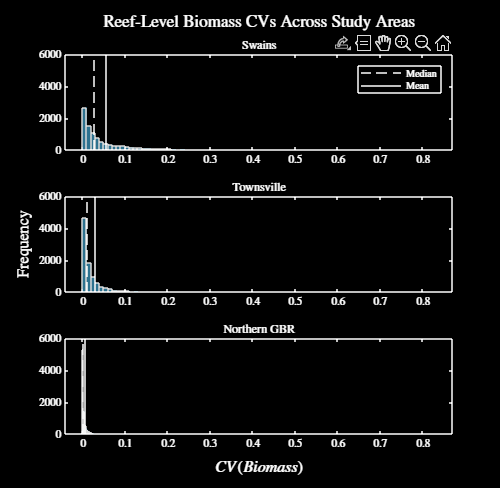

ans =     0.6945
    0.6944
    0.6945
    0.6944
    0.6945
    0.6947
    0.6941
    0.6943
    0.6943
    0.6945


% let's first look at the population CVs at each of the locations before
% moving on
figure
tL = tiledlayout(3, 1);

% plot the swains
var1(1) = nexttile;
histogram(simOutCellSwains{1}.stdBiomassObs(:) ...
    ./ simOutCellSwains{1}.meanBiomassObs(:))
xline(median(simOutCellSwains{1}.stdBiomassObs(:) ...
    ./ simOutCellSwains{1}.meanBiomassObs(:)), '--k')
xline(mean(simOutCellSwains{1}.stdBiomassObs(:) ...
    ./ simOutCellSwains{1}.meanBiomassObs(:)), '-k')
lG = legend("", "Median", "Mean");
title("Swains")

% plot the townsville area
var1(2) = nexttile;
histogram(simOutCellTowns{1}.stdBiomassObs(:) ...
    ./ simOutCellTowns{1}.meanBiomassObs(:))
xline(median(removeNaNs(simOutCellTowns{1}.stdBiomassObs(:) ...
    ./ simOutCellTowns{1}.meanBiomassObs(:))), '--k')
xline(mean(removeNaNs(simOutCellTowns{1}.stdBiomassObs(:) ...
    ./ simOutCellTowns{1}.meanBiomassObs(:))), '-k')
title("Townsville")

% plot the northern region
var1(3) = nexttile;
histogram(simOutCellNorth{1}.stdBiomassObs(:) ...
    ./ simOutCellNorth{1}.meanBiomassObs(:))
xline(median(simOutCellNorth{1}.stdBiomassObs(:) ...
    ./ simOutCellNorth{1}.meanBiomassObs(:)), '--k')
xline(mean(simOutCellNorth{1}.stdBiomassObs(:) ...
    ./ simOutCellNorth{1}.meanBiomassObs(:)), '-k')
title("Northern GBR")

% pretty up the figure
linkaxes(var1, "xy")
title(tL, "Reef-Level Biomass CVs Across Study Areas", 'interpreter', ...
    'latex')
xlabel(tL, "$CV(Biomass)$", 'interpreter', 'latex')
ylabel(tL, "Frequency", 'interpreter', 'latex')
darkFig()
figResize(1.3)

% we now need to look at this and plot the results - may as well just use a
% histogram for now because I'm lazy? idk

% hmmmmmmmmm we have data over 100 repetitions, each with 100 reefs, so it
% this is a bit tricky to think about methinks

## Setting Up Cape Study Area

% let's trial a number of these, but base our choices perhaps on the
% connectivity CVs, or maybe just the regions???? idfk

% let's first do one around Cape York
% var1 = [142.75, 144.2];
% var2 = [-12.5, -11.5];
var1 = [143, 144.1];
var2 = [-10.95, -10.3];
borderCape = [var1(1), var2(1); var1(2), var2(1); var1(2), var2(2); ...
    var1(1), var2(2); var1(1), var2(1)];

% find the reefs that fit in with the above border
reefIndsCape = zeros(nReefsCT, 1);
for i = 1:length(centroidsCT)

    % check if this fits into the border I have defined, along with a
    % minimum area tolerance for computational reasons
    c = centroidsCT(i, :);
    if c(1) > borderCape(1, 1) && c(1) < borderCape(2, 1) ...
            && c(2) > borderCape(1, 2) && c(2) < borderCape(3, 2)
        reefIndsCape(i) = 1;
    end

end
reefIndsCape = reefIndsCape > 0;
sum(reefIndsCape)

ans = 100

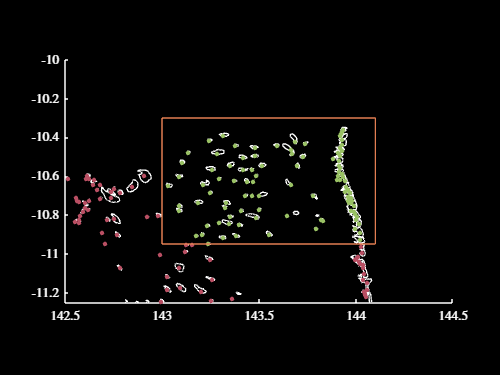

% look again at the reefs that were selected
figure
% var1 = [142.5, 144.5, -12.75, -11.25];
var1 = [142.5, 144.5, -11.25, -10];
plotShapeStruct(GBRShapeCT, [], [], [], [], var1)
plot(centroidsCT(~reefIndsCape, 1), centroidsCT(~reefIndsCape, 2), ...
    '.', 'Color', getColour('r'), 'MarkerSize', 10)
plot(centroidsCT(reefIndsCape, 1), centroidsCT(reefIndsCape, 2), ...
    '.', 'Color', getColour('g'), 'MarkerSize', 10)
plot(borderCape(:, 1), borderCape(:, 2), '-', 'Color', getColour('o'))
darkFig()

% let's now extract the meaningful information
nReefsCape = sum(reefIndsCape);

% those look good, so let's grab out the connectivity matrices and other
% things that I need
conMatsCape = conMatsCT;
for m = 1:nMatsCT
    areaStructCape.conMats{m} = conMatsCT{m}(reefIndsCape, reefIndsCape);
end
areaStructCape.areas = areasCT(reefIndsCape);
GBRShapeCape = GBRShapeCT(reefIndsCape);
areaStructCape.centroids = centroidsCT(reefIndsCape, :);
areaStructCape.reefInds = reefIndsCape;

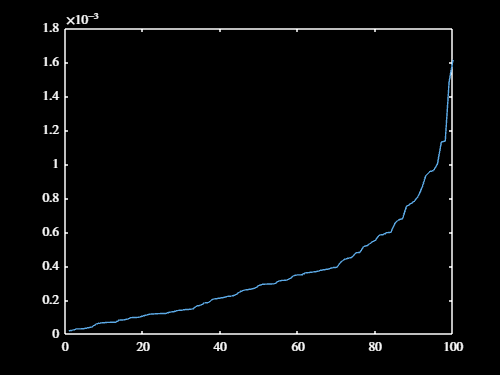

% look at the distribution of areas
figure
plot(sort(areaStructCape.areas))
darkFig()

max(areaStructCape.areas)

ans = 0.0016

sum(areaStructCape.areas)

ans = 0.0360

0.33 * sum(areaStructCape.areas)

ans = 0.0119

max(areaStructNorth.areas)

ans = 0.0186

sum(areaStructNorth.areas)

ans = 0.1142

0.33 * sum(areaStructNorth.areas)

ans = 0.0377

max(areaStructTowns.areas)

ans = 0.0134

sum(areaStructTowns.areas)

ans = 0.1850

0.33 * sum(areaStructTowns.areas)

ans = 0.0611

% let's look at the CVs now because I'm dumb
[meanConnCTCape, stdConnCTCape, ~, ~] ...
    = connectivityAnalysisReef(areaStructCape.conMats, eps);

## Setting Up Cairns Study Area

% let's look at another one haha awesome, this time around Cairns
var1 = [145, 146.5];
var2 = [-17, -15];
borderCairns = [var1(1), var2(1); var1(2), var2(1); var1(2), var2(2); ...
    var1(1), var2(2); var1(1), var2(1)];

% find the reefs that fit in with the above border
reefIndsCairns = zeros(nReefsCT, 1);
for i = 1:length(centroidsCT)

    % check if this fits into the border I have defined, along with a
    % minimum area tolerance for computational reasons
    c = centroidsCT(i, :);
    if c(1) > borderCairns(1, 1) && c(1) < borderCairns(2, 1) ...
            && c(2) > borderCairns(1, 2) && c(2) < borderCairns(3, 2) ...
            && areasCT(i) > 0.8875 * 10^-4
        reefIndsCairns(i) = 1;
    end

end
reefIndsCairns = reefIndsCairns > 0;
sum(reefIndsCairns)

ans = 100

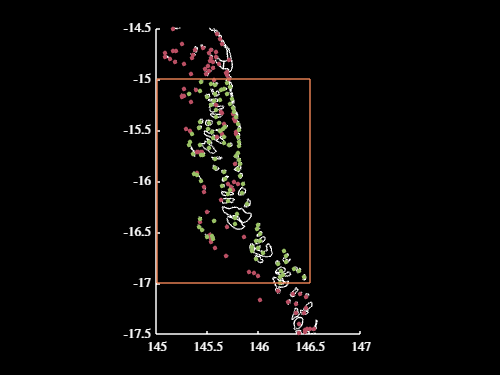

% look again at the reefs that were selected
figure
var1 = [145, 147, -17.5, -14.5];
plotShapeStruct(GBRShapeCT, [], [], [], [], var1)
plot(centroidsCT(~reefIndsCairns, 1), centroidsCT(~reefIndsCairns, 2), ...
    '.', 'Color', getColour('r'), 'MarkerSize', 10)
plot(centroidsCT(reefIndsCairns, 1), centroidsCT(reefIndsCairns, 2), ...
    '.', 'Color', getColour('g'), 'MarkerSize', 10)
plot(borderCairns(:, 1), borderCairns(:, 2), '-', 'Color', getColour('o'))
darkFig()

% let's now extract the meaningful information
nReefsCairns = sum(reefIndsCairns);

% those look good, so let's grab out the connectivity matrices and other
% things that I need
conMatsCairns = conMatsCT;
for m = 1:nMatsCT
    areaStructCairns.conMats{m} = conMatsCT{m}(reefIndsCairns, reefIndsCairns);
end
areaStructCairns.areas = areasCT(reefIndsCairns);
GBRShapeCairns = GBRShapeCT(reefIndsCairns);
areaStructCairns.centroids = centroidsCT(reefIndsCairns, :);
areaStructCairns.reefInds = reefIndsCairns;

% let's look at the CVs now because I'm dumb
[meanConnCTCairns, stdConnCTCairns, ~, ~] ...
    = connectivityAnalysisReef(areaStructCairns.conMats, eps);

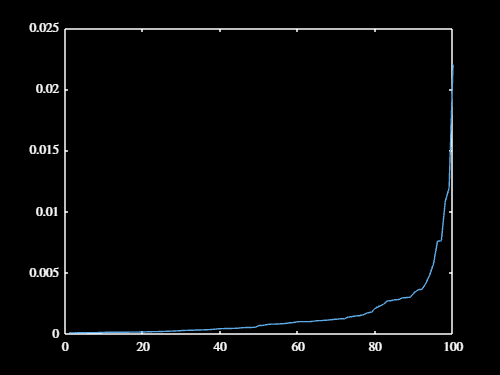

figure
plot(sort(areaStructCairns.areas))
darkFig()

sum(areaStructCairns.areas)

ans = 0.1582

0.33 * sum(areaStructCairns.areas)

ans = 0.0522

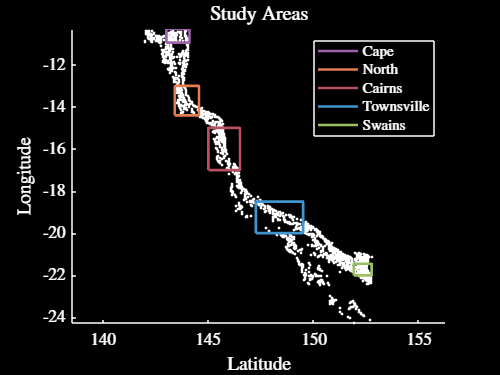

% do a plot of all the study areas quickly so I can figure out where shit
% is - just gonna do the centroids here, but can easily change it to go
% back to outlines later
% cool I hate my life now apparently
figure
hold on
plot(borderCape(:, 1), borderCape(:, 2), '-', 'Color', getColour('p'), ...
    'LineWidth', 2)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', getColour('o'), ...
    'LineWidth', 2)
plot(borderCairns(:, 1), borderCairns(:, 2), '-', 'Color', getColour('r'), ...
    'LineWidth', 2)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', getColour('b'), ...
    'LineWidth', 2)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', getColour('g'), ...
    'LineWidth', 2)
% plotGBRShape(GBRShapeCT)
plot(centroidsCT(:, 1), centroidsCT(:, 2), 'k.')
plot(borderCape(:, 1), borderCape(:, 2), '-', 'Color', getColour('p'), ...
    'LineWidth', 2)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', getColour('o'), ...
    'LineWidth', 2)
plot(borderCairns(:, 1), borderCairns(:, 2), '-', 'Color', getColour('r'), ...
    'LineWidth', 2)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', getColour('b'), ...
    'LineWidth', 2)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', getColour('g'), ...
    'LineWidth', 2)
axis equal
title("Study Areas")
xlabel("Latitude")
ylabel("Longitude")
legend("Cape", "North", "Cairns", "Townsville", "Swains")
setFontSize(14)
darkFig()

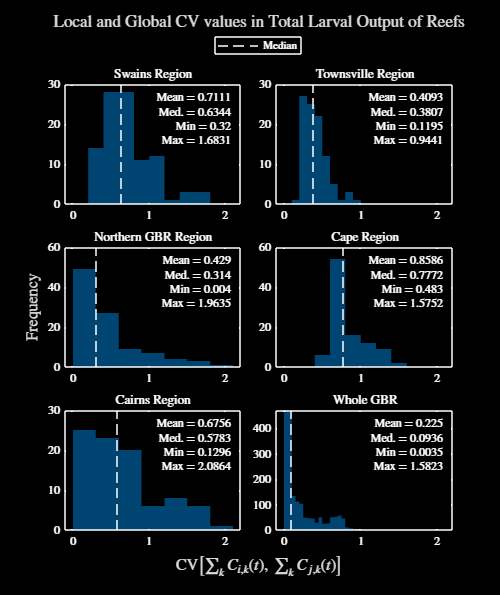

% look at the connectivity CVs
figure
plotConnectivityStats({stdConnCTSwains ./ meanConnCTSwains, ...
    stdConnCTTowns ./ meanConnCTTowns, stdConnCTNorth ./ meanConnCTNorth, ...
    stdConnCTCape ./ meanConnCTCape, stdConnCTCairns ./ meanConnCTCairns, ...
    stdConnCT ./ meanConnCT}, "CVLoc", ["Swains Region", ...
    "Townsville Region", "Northern GBR Region", "Cape Region", ...
    "Cairns Region", "Whole GBR"])
figResize(1.9, 1.2)
darkFig()

% I think for now, let's just leave it here in terms of the study areas - I
% could throw one more around Mackay, but 5 is probably fine for the time
% being

## Running New Simulations

% alright, gonna do the Cape region first

% ensure parallel processes are cancelled
if exist('futureVecFinCape', 'var')
    cancelFutureVec(futureVecFinCape);
    clear futureVecFinCape
end

% run in parallel
methodStringVec = ["none", "random", "finalBiom", "finalLarvCont", ...
    "MPTBiom", "MPTBiom", "MPTBiom", "MPTBiom", "MPTBiom", ...
    "MPTLarvCont", "MPTLarvCont", "MPTLarvCont", "MPTLarvCont", ...
    "MPTLarvCont"];
weightVec = [0, 0, 0, 0, 1, 0.75, 0.5, 0.25, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:length(methodStringVec)
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    futureVecFinCape(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructCape, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 14 workers.


if checkFutureVec(futureVecFinCape)
    for i = 1:length(futureVecFinCape)
        simOutCellCape{i} = fetchOutputs(futureVecFinCape(i));
    end
    % clear futureVecFinCape
end

Futures have completed succesfully.


% now go for the Cairns region

% ensure parallel processes are cancelled
if exist('futureVecFinCairns', 'var')
    cancelFutureVec(futureVecFinCairns);
    clear futureVecFinCairns
end

% run in parallel
methodStringVec = ["none", "random", "finalBiom", "finalLarvCont", ...
    "MPTBiom", "MPTBiom", "MPTBiom", "MPTBiom", "MPTBiom", ...
    "MPTLarvCont", "MPTLarvCont", "MPTLarvCont", "MPTLarvCont", ...
    "MPTLarvCont"];
weightVec = [0, 0, 0, 0, 1, 0.75, 0.5, 0.25, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:length(methodStringVec)
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    futureVecFinCairns(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructCairns, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct);
end

% extract results
if checkFutureVec(futureVecFinCairns)
    for i = 1:length(futureVecFinCairns)
        simOutCellCairns{i} = fetchOutputs(futureVecFinCairns(i));
    end
    % clear futureVecFinCairns
end

Futures have completed succesfully.


% note - in case I need this info later, with 12 of these parallel
% processes running at once, I'm using 22gb about of ram

% check that this ordering is right
% for i = 1:length(simOutCellSwains)
%     simOutCellSwains{i}.methodStruct.methodInd + " " ...
%         + simOutCellSwains{i}.methodStruct.meanVarWeight
% end